clear; close all;

Harrison Robel, Partner: Karen Gong

## Problem 1: Bad Data

Sometimes our data isn't perfect and we need to be able to sort through it to make sure we have a good data set. For the first problem in this lab we are going to look at temperature readings at 12 Kelvin with a 0.4 degree precision. The temperature readout was not alway accurate and sometimes it came out at very high temperatures or very low temperatures. The data can be a nussance to the experiment so we will want to throw that data out. We want to come up with a method that can remove all the unprecise measurements from the data in order to get a cleaner data set. To show this we will make a distribution of 100000 normally distributed data points with a mean of 12 (because of 12 K) and a standard deviation of 0.4 (precision). Added onto this 'good' data set will be a 'bad' data set [10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7]. Some of this data is close to the 'good' data while some is very far off.

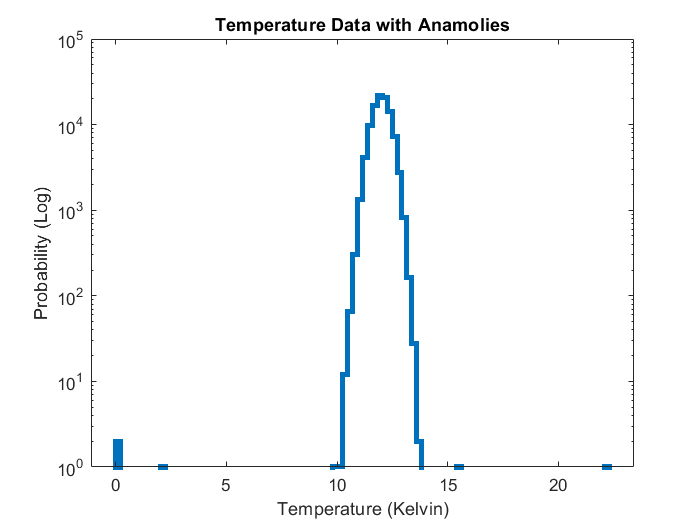

badnorm = random('Normal',12,0.4, [1,100000]);
badnorm = [badnorm, 10.0, 10.3, 2.1, 0.0, 0.0, 15.6, 22.3, 12.7];
histogram(badnorm,100,'DisplayStyle',"stairs",'LineWidth',3)
set(gca,'YScale','log')
title('Temperature Data with Anamolies')
xlabel('Temperature (Kelvin)')
ylabel('Probability (Log)')

This data only have 8 bad data points but we would still like it if we can clean it up because the significance of the bad data.To do this we need to start with analysis our data with plots. It is clear from the semi-log plot that there are large outliers on this plot. The 0,2,16,22 area have large spikes on the data that don't seem to be due to the distribution and would be exteremly unlikely. This makes it clear that we have some problem with our data and want to straighten this out. The question we are trying to answer is; what test can we create in order to remove the bad data and how accurate is it in removing only the bad data and not the good data? Mathetmaticaly that can mean removing the bottom and top percentage of data points that are outside a certain limit (let's say +/- 1.0 K). To do this I found the probability that you will find values below 11.0 and above 12.8 in a normal distribution and set those numbers to be my lower and upper bound for removing outliers.

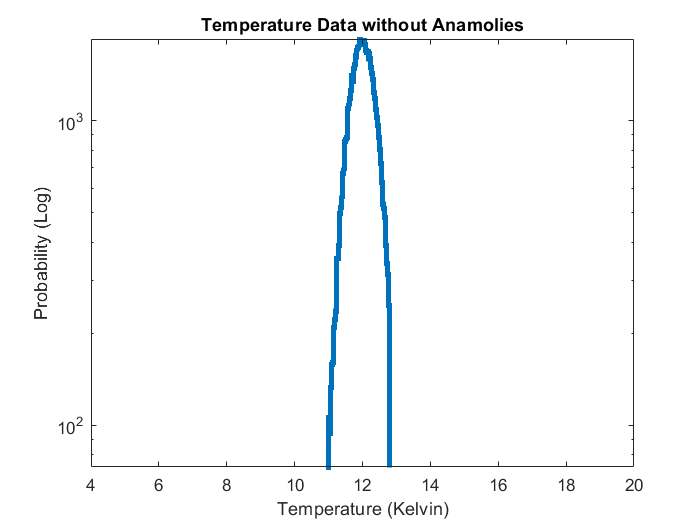

boundlower = 11.0; 
boundupper = 12.8;
problower = normcdf(boundlower,12,0.4) * 100;
probupper = normcdf(boundupper,12,0.4) * 100;
goodnorm = rmoutliers(badnorm,'percentiles',[problower probupper]);

histogram(goodnorm,100,'DisplayStyle',"stairs",'LineWidth',3)
set(gca,'YScale','log')
xlim([4 20])
title('Temperature Data without Anamolies')
xlabel('Temperature (Kelvin)')
ylabel('Probability (Log)')


% Table
number1 = size(goodnorm,2);
number2 = size(badnorm,2) - size(goodnorm,2) - 1;
rownames = {'Your Test Good';'Your Test Bad'};
True_T = [number1; (number2-7)];
Bad_T = [7;1];
table(True_T, Bad_T,'RowNames',rownames)

ans = 2×2 table
                      True_T    Bad_T
                      ______    _____

    Your Test Good    97112       7  
    Your Test Bad      2888       1  


The truth table shows us how accurate we were in our test. We managed to keep the majority of our good data, and removed all but one bad data points. However, these numbers do depend on the threshold that is introduced. The thresholds given in this example were 11.0 and 12.8. The test would cut off any data points not within these two points and therefore we could change the thresholds to keep more good data, or I we wanted to be extra cautious shrink it to exclude more good data. The amount of data that we exclude is predictible because we are using a percentage to remove data points, we can find the probability that the background distribution will cause a data point to be within those precentages. There is one case of a bad data point getting into the data. This is because we have a bad data point that is [12.7] and our bounds are set to [11.0 12.8] therefore that point gets included. This could be avoided by lowering the thresholds, but this would exclude more good data.

## Problem 2: Asteroids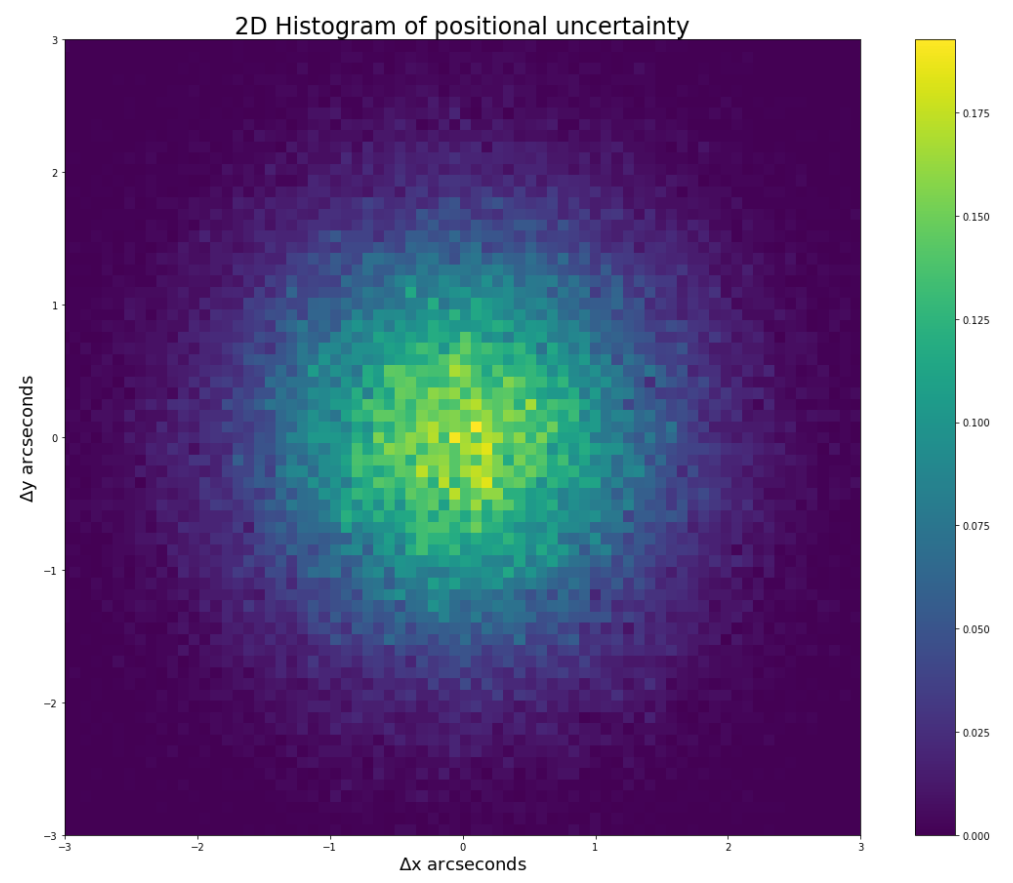

The graph above is a two-dimensional gaussian distribution of the distortion of images due to the atmosphere. The background measures the distortion of how far stationary stars shift from the atmosphere in arcseconds in both the x and y direction. An asteroid is detected when a movement across the image is significantly larger than the background noise. To see how far an asteroid would have to move in order to be considered significant (5 sigma or more) we can find the distance from a Rayleigh distribution. The reason we can use a Rayleigh distribution is because distance is given by $d=\sqrt{X_1^2 +X_2^2 }$ which using related distribution tables we can see that that relationship between two Gaussians gives a Rayleigh distribution in one dimension because the two variables are independent of each other. The question we are hoping to answer is; how far (in arcseconds) does an object need to move across the image in order to produce a signal of 5 or more sigma? To do this in math we find the probability corresponding to 5 sigma, either by looking it up or by calculating it with a Gaussian CDF function. Then with the probability we found for 5 sigma we can use the inverse Rayleigh CDF function to find a value of distance.

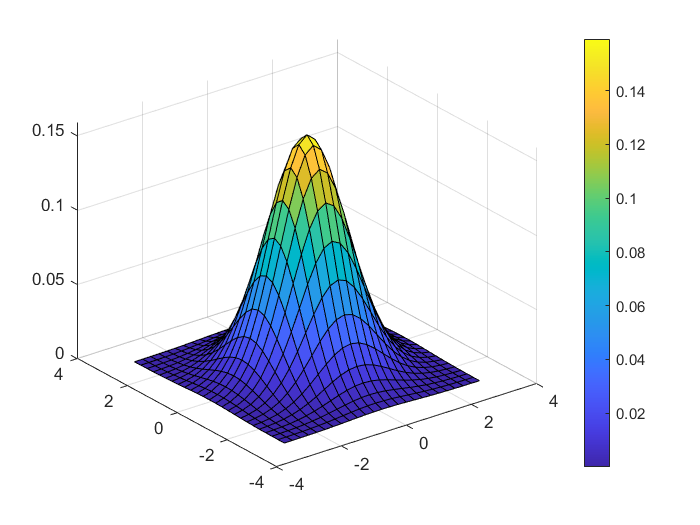

mu = [0 0]; Sigma = [1 1];
[X1,X2] = meshgrid(linspace(-3,3,25)', linspace(-3,3,25)');
X = [X1(:) X2(:)];
p = mvnpdf(X, mu, Sigma);
surf(X1,X2,reshape(p,25,25));
colorbar


prob = normcdf(5);
distance = raylinv(prob,1)

distance = 5.4891

After all the math is completed we can see that the distance needed in order to be considered significant is about 5.5 arcseconds. This is a fairly large distance compared to the width of the screen, which makes sense because it needs to be significant enough to reach 5 sigma and leave little doubt. 

## Problem 3: Moon's Cosmic Ray Shadow

Gamma-Ray detectors have the problem of dealing with a high energy cosmic rays that enter the detector and cause a signal. The cosmic rays are usually charged high energy particles that come from all directions of space. The sun and the moon, however, are large enough in the sky where they will sometimes block the cosmic rays from space and turn up as a hole in the background. If we look at a moon sized point in the sky with a gamma-ray detector we will expect to see about 1 cosmic ray per minute. If we observe the moon for 8 hours a night with a gamma-ray detector we see 6800 cosmic rays over a 15 day period. Observing a blank place in the sky we should expect to see 7200 cosmic rays over the same time interval. The question then becomes; if we observe the moon for 15 days over 8 hours a day, how significant is the shadow that the moon casts on the detector? To ask this mathematically we need to ask; what is the probability that the dip in cosmic rays or less could have been caused by the background distribution. This question has to be approached carefully because the time interval that we are looking over creates a large trials factor that we need to consider. Because we are getting a discrete amount of counts with an average of just 1 a minute, the background will be a poisson distribution. Then in order to achieve a distribution of 15 days we need to mulitply by the total amount of time that we are spending observing the moon in minutes. This gives us a distribution that we could expect over that time interval.

time = 8*60*15;
avebackground = 1.0;
counts = 6800;
avemoon = counts/time;
backdist = makedist("Poisson",'lambda',avebackground);
expcounts = cdf(backdist,avemoon)*time;
sigma = normcdf(expcounts)

sigma = 1

As we can see from our sigma, the significance of the moon shadow is not very large. With a sigma of 1 it is very probable that the dip in counts came from random chance. This may be a suprising result but because we would have expected to read 7200 counts the drop of 400 is not very significant on the scale of several thousands of counts and is very likely to have occured from random chance. This could be the case for two reasons; 1) the cosmic rays deflect around the moon and enter the telescope anyways or 2) the cosmic rays are coming from a different directions and avoiding the moon entirely. 